# **Introducció a la programació d'Arduino mitjançant MATLAB/Simulink**

En aquest document es descriu a l'usuari els primers passos a seguir quan fem servir la placa de control Arduino amb el model de Simulink. Prèviament, s'introduiran els paquets de suport MATLAB i Simulink per Arduino i es descriurà com configurar Simulink per poder interactuar amb Arduino (en aquest cas s'usarà un Arduino Due). Finalment, es faran diversos exercicis que fa a les entrades i sortides analògiques i digitals.

**OBJECTIU: Aprendre a usar els blocs específics d'entrades i sortides analògiques d'Arduino en Simulink.**

% Si vols obrir el model de Simulink per fer experiments = true
% Si no desitja obrir el model de Simulink = false
OpenModel = true;

# Paquets de Suport

Gràcies als paquets de suport de MATLAB/Simulink per al hardware Arduino, podem comunicar-nos i interactuar amb una placa Arduino. Aquests paquets permeten adquirir dades de sensors analògics i digitals des de la placa Arduino i controlar altres dispositius amb sortides analògiques i digitals o de modulació PWM creant així una plataforma versàtil i de baix cost.

La seva instal·lació és molt senzilla, per a això segueix els següents passos:

- A la pestanya "Home" > "Adds-Ons" > "Get Adds-Ons"

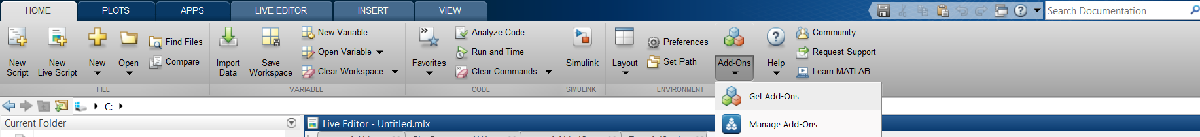

- Trobar els paquets esmentats i clicar en el botó instal·lar.

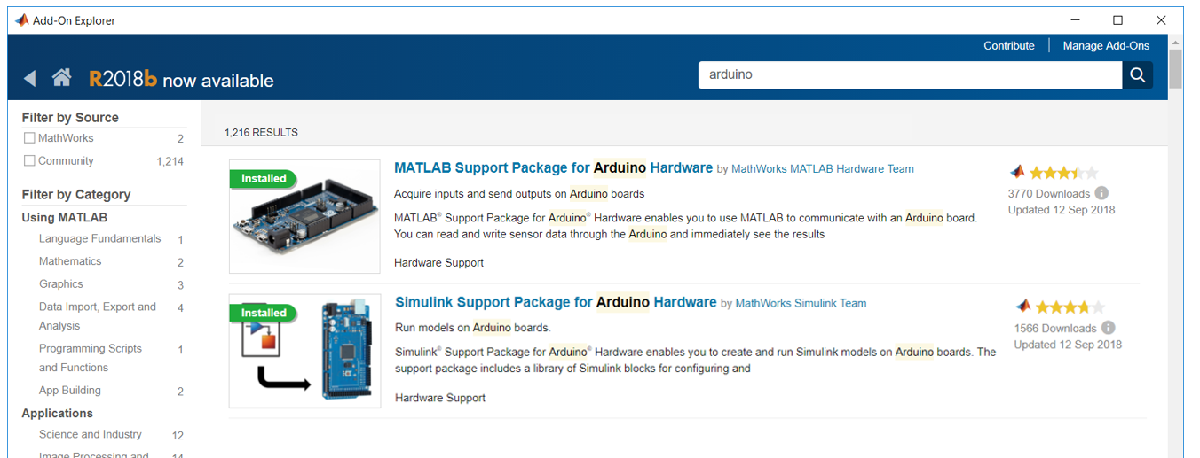

Per a més informació:

***Suport de MATLAB per a Arduino***

Pàgina web: [https://es.mathworks.com/hardware-support/arduino-matlab.html](https://es.mathworks.com/hardware-support/arduino-matlab.html) 

Documentació: [http://www.mathworks.com/help/supportpkg/arduinoio/](http://www.mathworks.com/help/supportpkg/arduinoio/)

Exemples: [https://es.mathworks.com/help/supportpkg/arduinoio/examples.html](https://es.mathworks.com/help/supportpkg/arduinoio/examples.html) 

**Suport de Simulink per Arduino**

Pàgina web: [https://es.mathworks.com/hardware-support/arduino-simulink.html](https://es.mathworks.com/hardware-support/arduino-simulink.html) 

Documentació: [http://www.mathworks.com/help/supportpkg/arduino/](http://www.mathworks.com/help/supportpkg/arduino/)

Exemples: [https://es.mathworks.com/help/supportpkg/arduino/examples.html](https://es.mathworks.com/help/supportpkg/arduino/examples.html) 

# Configuració per a MATLAB

Per a connectar-te a un hardware oficial d'Arduino.

a = arduino()

Si utilitzeu un hardware Arduino no oficial (clon), especifiqueu el port i el nom de la placa per establir la connexió.

a = arduino('COM3','Uno')

El paquet de suport de MATLAB per Arduino proporciona una llista de funcions que permeten accedir a entrades i sortides digitals i analògiques: 

- configurePin: estableix la direccionalitat (entrada o sortida) d'un pin digital. 

- writeDigitalPin - escriu en una sortida digital. 

- readDigitalPin - llegeix una entrada digital. 

- writePWMDutyCycle: escriu en una sortida PWM, cicle de treball en 0-1. 

- writePWMVoltage: escriu en una sortida PWM, cicle de treball en 0-5 (volts efectius). 

- readVoltage - llegeix una entrada analògica.

Podeu trobar una descripció detallada de cada funció en MATLAB amb la seva ajuda o mitjançant la documentació proporcionada a l'apartat anterior.

# Configuració per Simulink

A l'hora de configurar Simulink per poder interactuar amb Arduino hem de tenir en compte tres passos. El primer seria triar el dispositiu a utilitzar; el segon, la manera en què volem fer-lo servir i l'últim, el temps d'execució.

**Elecció de dispositiu** 

Per especificar les configuracions del hardware a utilitzar, en Simulink seleccionarem **Simulation > Model Configuration Parameters**, o farem clic al botó de “*Model Configuration Parameters button*”   , el qual es troba a la barra d'eines de Simulink, com es pot analitzar en la següent imatge.

Un cop dins, seleccionarem la pestanya **Hardware Implementation** i en l'opció **Hardware Board** seleccionarem el nostre hardware a utilitzar, en aquest cas, com s'ha esmentat anteriorment, s'usarà un Arduino Due.

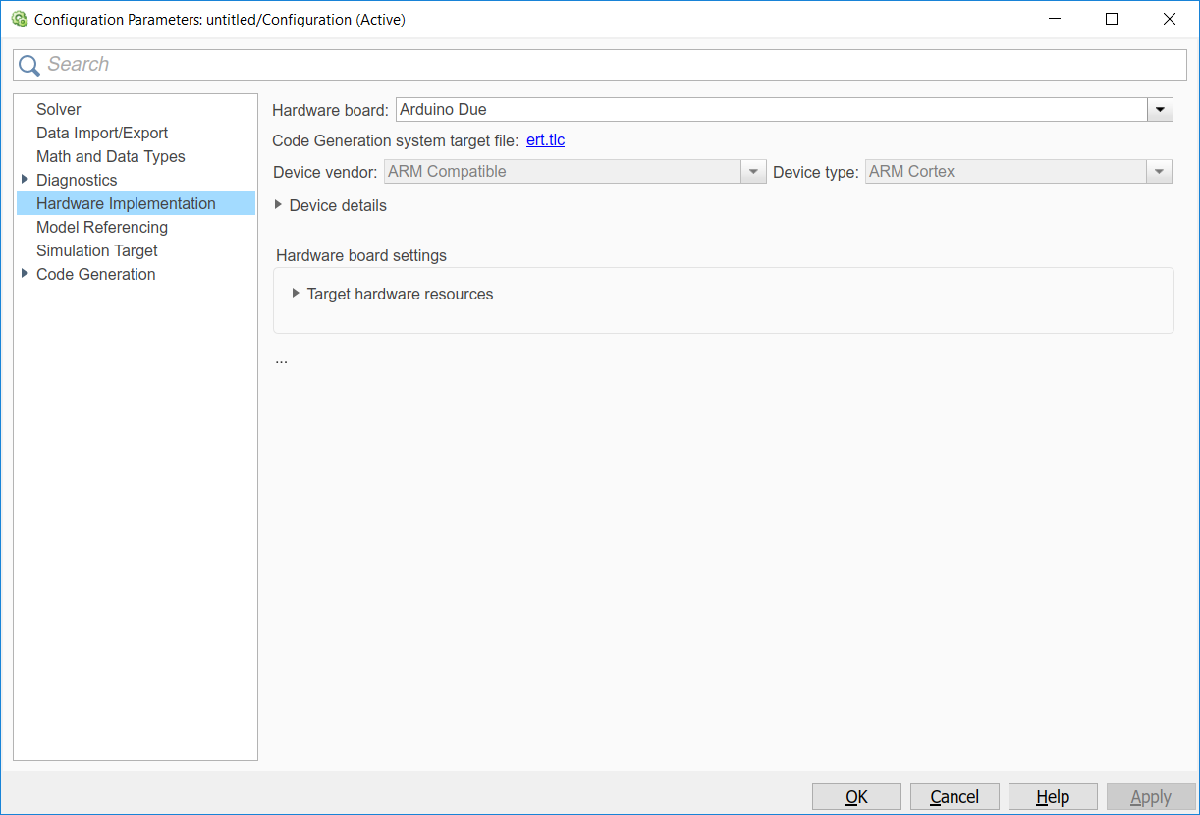

**Mode de simulació**

Com el hardware a utilitzar és un hardware extern, la manera en què s'executa el model de Simulink ha de ser “***external***”. D'aquesta manera, connectem el diagrama de blocs creat en Simulink amb la nostra aplicació, el qual executa el model en el hardware de destinació.

A més d'això, també ens aporta l'opció de compilar el codi i transferir-lo a nostre microcontrolador, així, el model no haurà d'estar connectat a Simulink. Per a això s'usa el botó "***Deploy to Hardware***".

**Temps d'execució**

El tercer concepte a tenir en compte és el temps d'execució, gràcies a aquesta opció, podem triar el temps que es desitja que el model aquest en execució. Si es desitja executar fins a una certa interrupció, es delimitarà escrivint “***Inf***”.

Tenint en compte aquests tres passos, podem ara interactuar amb el Arduino mitjançant Simulink. És per això que en la següent secció es realitzaran diversos exercicis amb els quals aprendrem el bàsic per poder manejar-nos amb això.

# Exercicis

En aquesta secció es realitzen diversos exercicis amb els quals s'interioritzarà més fàcilment els conceptes d'entrades i sortides digitals i analògics d'Arduino usant per a això el full de Simulink.

***Exercici 1******: Sortida digital***

Aquest primer exercici tracta d'encendre el led integrat del microcontrolador. Aquest led està incorporat en gairebé totes les plaques d'Arduino i la seva enumeració varia respecte al model en ús. En el cas de l'Arduino Due, aquest led està connectat al pin 13, és per això que s'ha realitzat el següent diagrama de blocs.

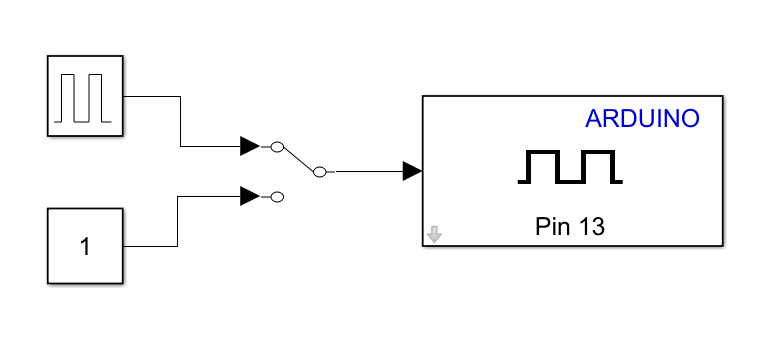

Gràcies a aquest diagrama de blocs podrem analitzar com encendre un led mitjançant 0 i 1 o mitjançant un senyal de polsos accionant per a això l'interruptor manual.

Per saber a quina pin està connectat el led integrat de la teva placa Arduino: [https://www.arduino.cc/en/Tutorial/Blink](https://www.arduino.cc/en/Tutorial/Blink) 

if OpenModel
    cd('..')
    FolderName = [pwd filesep 'Common' filesep 'P0'];
    addpath([pwd filesep 'Common' filesep 'P0']);
    open DigitalOut.slx
end

***Exercici 2:****** Entrada digital***

Aquest segon exercici consisteix a obtenir un senyal digital mitjançant un botó. Quan el botó aquest premut, cal obtenir un 1 booleà en el scope de Simulink. Per tant, quan no s'acciona el botó, el que obtindrem serà un 0. Per això, s'ha creat el següent diagrama de blocs.

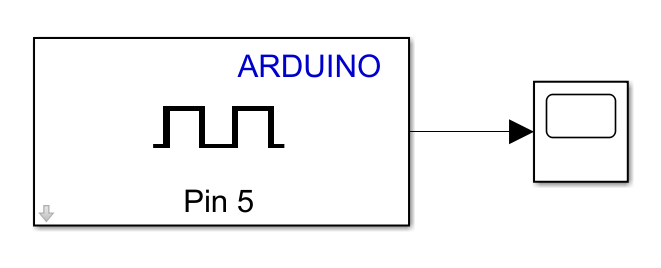

Al costat del següent circuit:

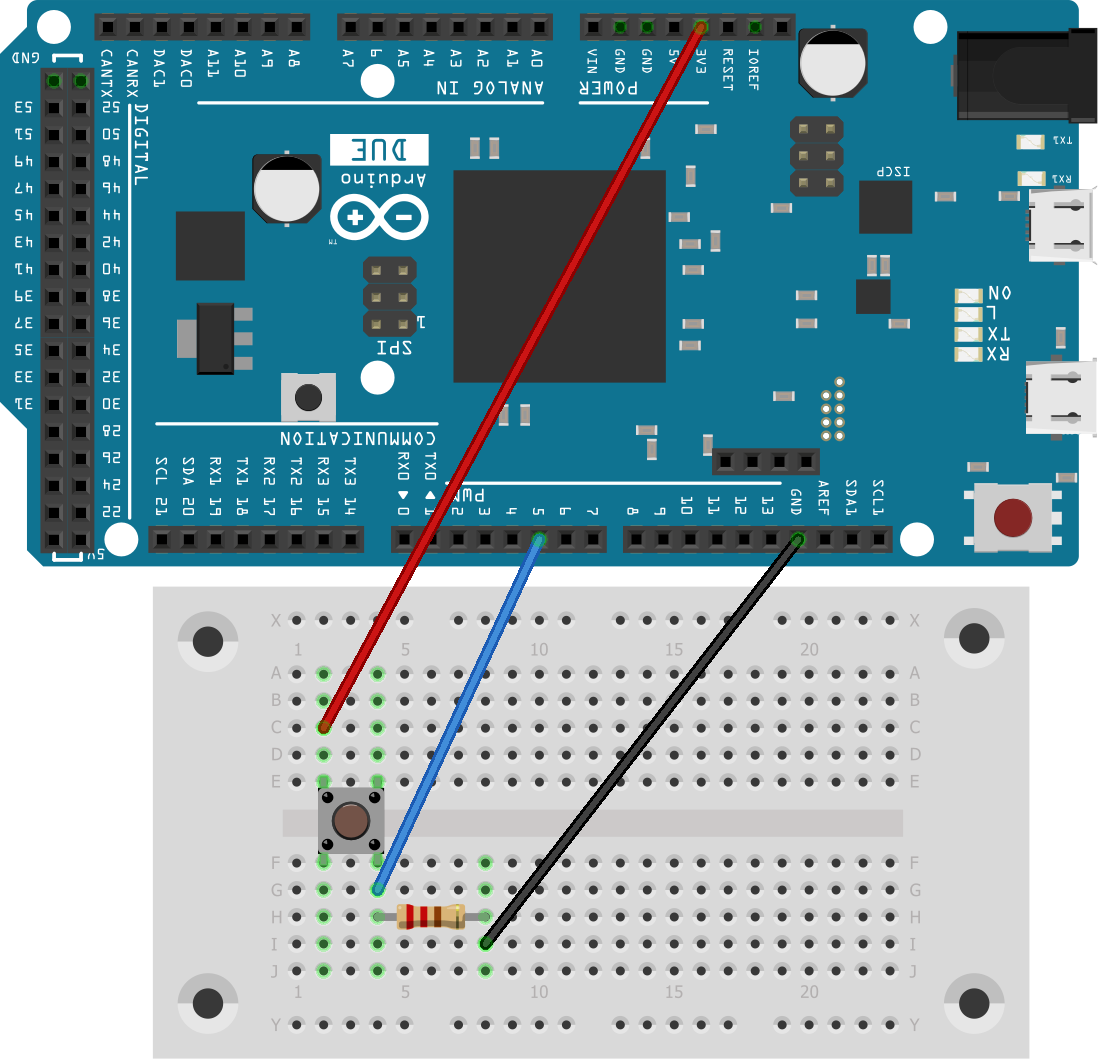

if OpenModel
    FolderName = [pwd filesep 'Common' filesep 'P0'];
    addpath([pwd filesep 'Common' filesep 'P0']);
    open DigitalIn.slx
end

***Exercici 3:****** S*****ortida analògica**

Es desitja encendre un led mitjançant senyal analògic. Per a això, farem servir els pins anomenats DAC de l'Arduino Due. Aquests pins són els encarregats de convertir un senyal digital a analògica. Es desitja encendre i apagar un led progressivament i a diferents freqüències, és per això que s'ha dissenyat el següent diagrama de blocs.

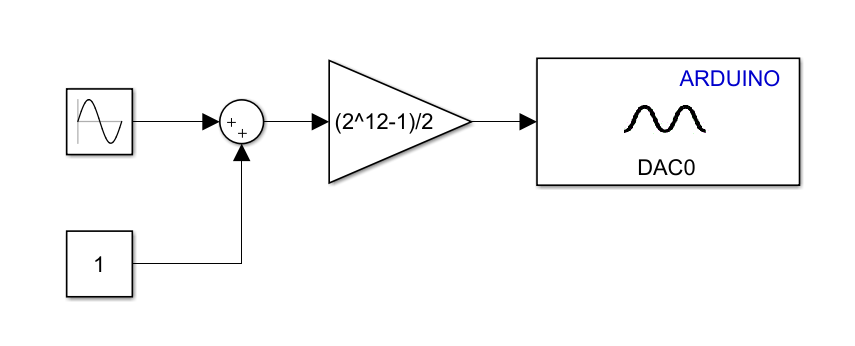 

Se li aplica un senyal sinusoïdal centrada en 0.5 i d'amplitud de 0.5. Amb la qual cosa el led canviarà a la freqüència del senyal senoida. Per a això, s'ha creat el següent circuit:

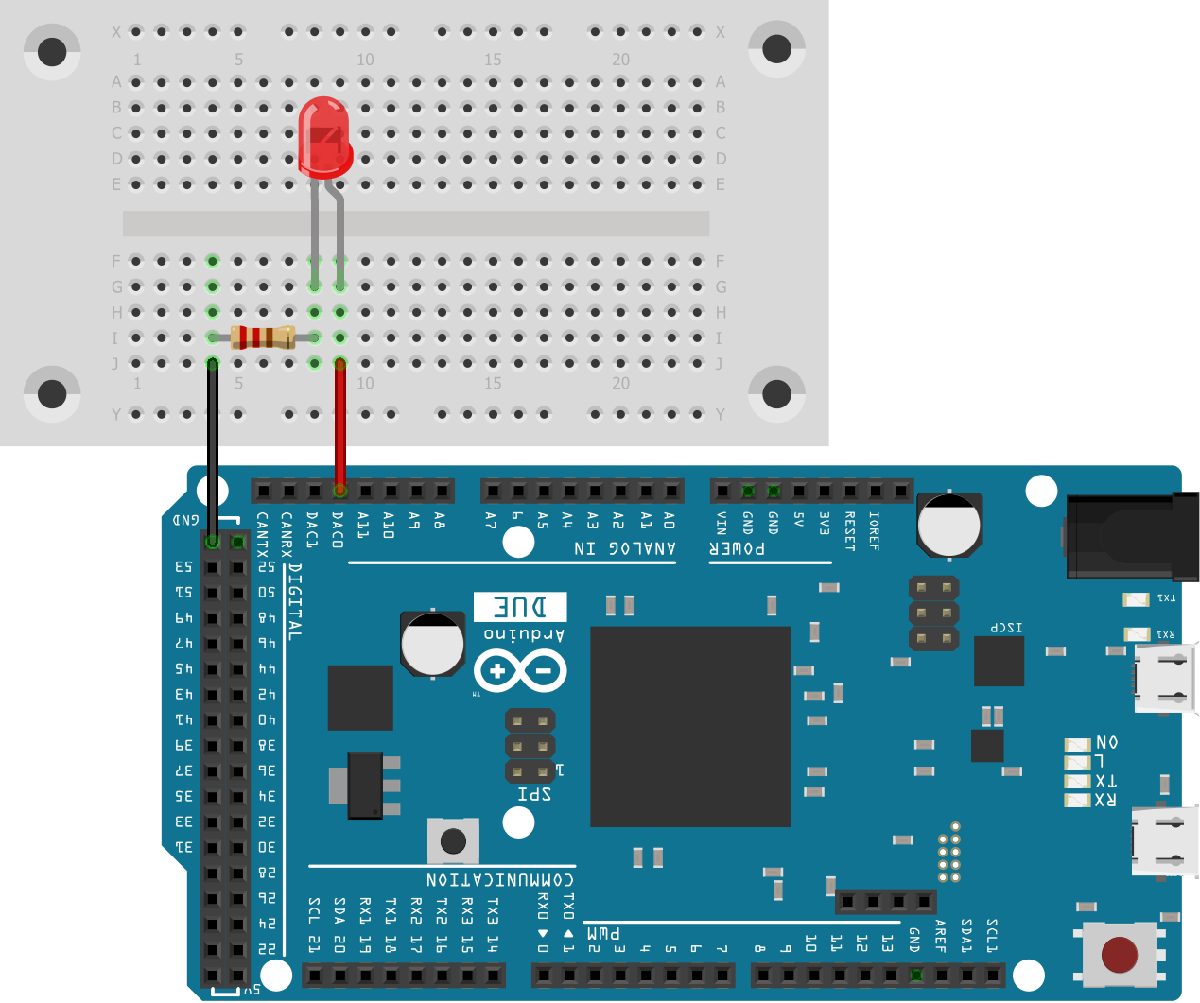

if OpenModel
    FolderName = [pwd filesep 'Common' filesep 'P0'];
    addpath([pwd filesep 'Common' filesep 'P0']);
    open AnalogOut.slx
end

***Exercici 4:*** **Entrada analògica**

Finalment, es vol obtenir un senyal analògic. Per a això s'ha utilitzat un potenciòmetre i s'ha dissenyat el següent diagrama de blocs.

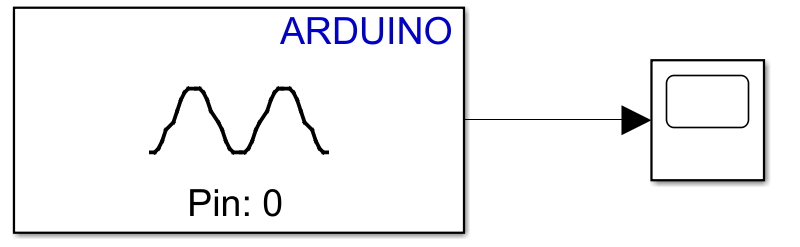

En aquest cas, el circuit creat és el següent:

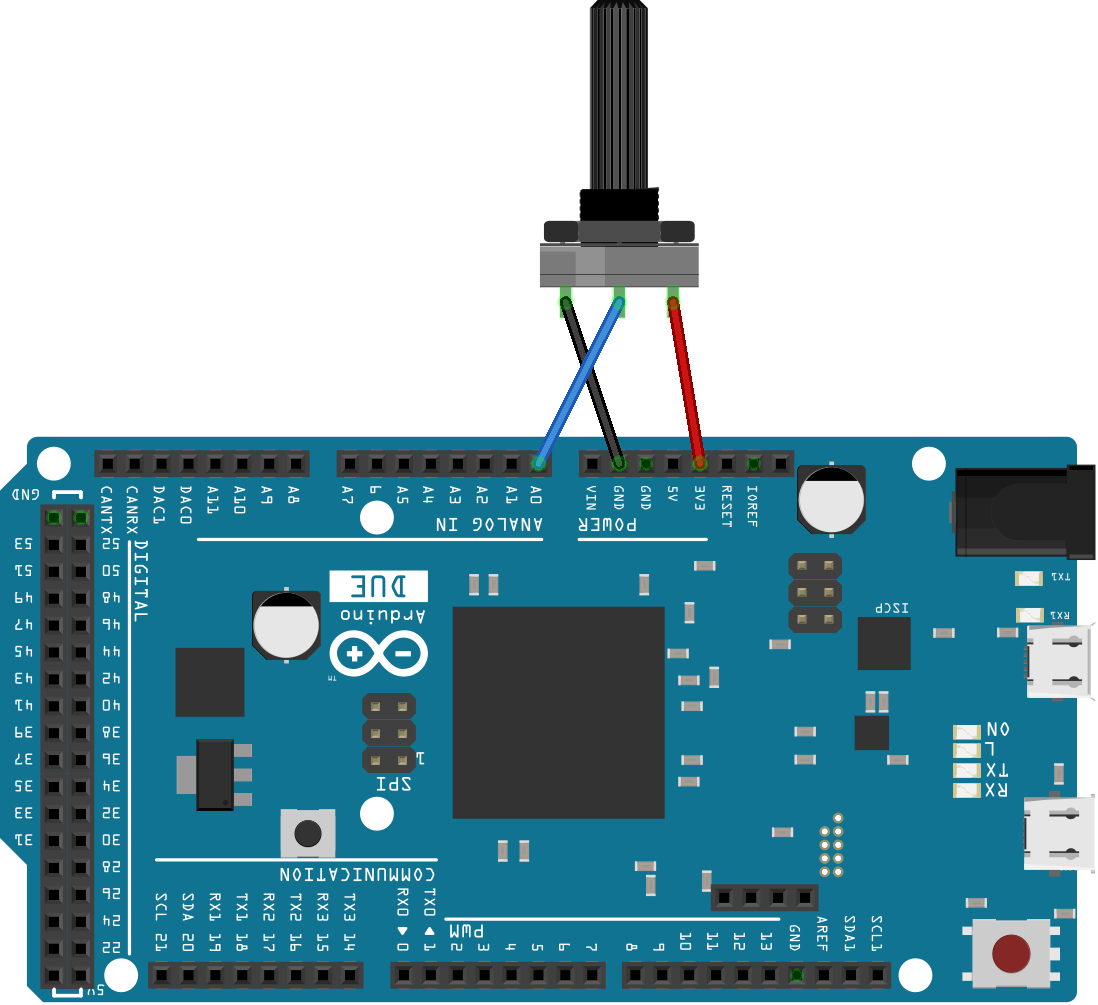

if OpenModel
    FolderName = [pwd filesep 'Common' filesep 'P0'];
    addpath([pwd filesep 'Common' filesep 'P0']);
    open AnalogIn.slx
end

***Conclusió:***

Un cop entenent aquests quatre conceptes es poden crear diagrames de blocs on es barregin tots aquests conceptes esmentats anteriorment i poder així crear un sistema de control. Per a més exemples d'Arduino en MATLAB o Simulink:

Exemples MATLAB & Arduino: [https://es.mathworks.com/help/supportpkg/arduinoio/examples.html](https://es.mathworks.com/help/supportpkg/arduinoio/examples.html) 

Exemples Simulink & Arduino: [https://es.mathworks.com/help/supportpkg/arduino/examples.html](https://es.mathworks.com/help/supportpkg/arduino/examples.html) 